clear; clc; close all;

% Nodal coordinates: [x y]
node = [ ...
    0.0   0.0  ;  % 1
    1.0   0.0  ;  % 2
    2.0   0.0  ;  % 3
    3.0   0.0  ;  % 4
    0.5   0.5  ;  % 5 (top)
    1.5   0.5  ;  % 6
    2.5   0.5  ]; % 7

% Element connectivity (node_i, node_j)
elem = [ ...
    1 2; 2 3; 3 4;          % bottom chords
    5 6; 6 7;               % top chords
    1 5; 2 5; 2 6; 3 6; 3 7; 4 7];  % diagonals/uprights

ne = size(elem,1); nn = size(node,1);

% Material & section (per element or uniform)
E  = 200e9;                         % Young's modulus (Pa)
A  = 4e-4*ones(ne,1);               % Area (m^2), uniform here
Ee = E*ones(ne,1);                  % E per element

% Boundary conditions: fix node 1 (x,y) and node 4 (y only) as example
% DOF ordering per node: [ux uy]
fixed = [ ...
    1 1;  % node 1, ux fixed
    1 2;  % node 1, uy fixed
    4 2]; % node 4, uy fixed

% Loads: [node Fx Fy] (N). Downward point loads on top nodes.
loadcase = [ ...
    5  0  -2000;
    6  0  -2000;
    7  0  -2000];

% Optional: add a small horizontal load somewhere, e.g.,
% loadcase = [loadcase; 3 1000 0];

%% -------------------- Assemble & solve ------------------------
[K, Ls, cs, ss] = assembleGlobalStiffness(node, elem, Ee, A);   % global K
F = zeros(2*nn,1);
for i = 1:size(loadcase,1)
    n   = loadcase(i,1);
    Fx  = loadcase(i,2);
    Fy  = loadcase(i,3);
    F(2*n-1) = F(2*n-1) + Fx;
    F(2*n  ) = F(2*n  ) + Fy;
end

% Build fixed DOF index list
fixDOF = unique(2*fixed(:,1) + (fixed(:,2)==1)*(-1) + (fixed(:,2)==2)*(0));
% Explanation: DOFs are [ux1 uy1 ux2 uy2 ...]
% For (node i, dof 1=ux,2=uy) -> global DOF = [2*i-1, 2*i]

gFix = zeros(size(fixed,1),1);
for k = 1:size(fixed,1)
    i = fixed(k,1); d = fixed(k,2);
    gFix(k) = 2*i - (d==1) ;  % ux -> 2*i-1, uy -> 2*i
end
gFix = unique(gFix);

allDOF = (1:2*nn)';
freeDOF = setdiff(allDOF, gFix);

% Solve Kff * Uf = Ff  -> displacements
Uf = K(freeDOF, freeDOF) \ F(freeDOF);
U  = zeros(2*nn,1);
U(freeDOF) = Uf;

% Reactions at fixed DOFs
R = K*U - F;
reactions = [gFix, R(gFix)];

%% -------------------- Post-processing -------------------------
[Nm, Sm] = memberForces(node, elem, Ee, A, U);   % axial force & stress

% Print a brief report
fprintf('--- Truss FEM Report ---\n');

--- Truss FEM Report ---


fprintf('Max disp (abs): %.5e m at DOF %d\n', max(abs(U)), find(abs(U)==max(abs(U)),1));

Max disp (abs): 3.19638e-04 m at DOF 12


fprintf('Member forces (N): min = %.2f, max = %.2f\n', min(Nm), max(Nm));

Member forces (N): min = -4242.64, max = 5000.00


fprintf('Member stresses (MPa): min = %.2f, max = %.2f\n', min(Sm)/1e6, max(Sm)/1e6);

Member stresses (MPa): min = -10.61, max = 12.50


fprintf('\nReactions (DOF, N):\n'); disp(reactions);


Reactions (DOF, N):
   1.0e+03 *

    0.0010   -0.0000
    0.0020    3.0000
    0.0080    3.0000



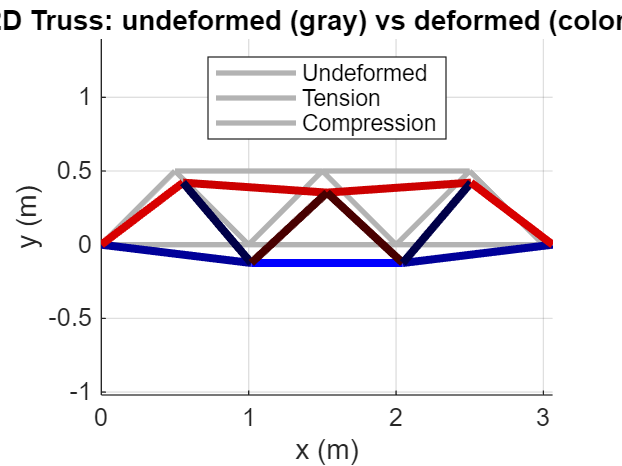


% Visualization
scale = chooseDeformScale(node, U, 0.05);  % ~5% of max span
plotTruss(node, elem, U, Nm, scale);


%% -------------------- Local functions -------------------------

function [K, Ls, c, s] = assembleGlobalStiffness(node, elem, E, A)
    nn = size(node,1);
    ne = size(elem,1);
    ndof = 2*nn;
    K = zeros(ndof, ndof);
    Ls = zeros(ne,1); c = zeros(ne,1); s = zeros(ne,1);

    for e = 1:ne
        i = elem(e,1); j = elem(e,2);
        xi = node(i,1); yi = node(i,2);
        xj = node(j,1); yj = node(j,2);

        dx = xj - xi; dy = yj - yi;
        L  = sqrt(dx^2 + dy^2); Ls(e) = L;
        ce = dx/L; se = dy/L; c(e)=ce; s(e)=se;

        ke = (E(e)*A(e)/L) * [ ce*ce  ce*se  -ce*ce -ce*se;
                               ce*se  se*se  -ce*se -se*se;
                              -ce*ce -ce*se   ce*ce  ce*se;
                              -ce*se -se*se   ce*se  se*se ];

        dof = [2*i-1 2*i 2*j-1 2*j];
        K(dof,dof) = K(dof,dof) + ke;
    end
end

function [N, S] = memberForces(node, elem, E, A, U)
    ne = size(elem,1);
    N  = zeros(ne,1);   % axial force
    S  = zeros(ne,1);   % axial stress
    for e = 1:ne
        i = elem(e,1); j = elem(e,2);
        xi = node(i,1); yi = node(i,2);
        xj = node(j,1); yj = node(j,2);

        dx = xj - xi; dy = yj - yi;
        L  = sqrt(dx^2 + dy^2);
        c  = dx/L; s = dy/L;

        dof = [2*i-1 2*i 2*j-1 2*j];
        ue  = U(dof);
        % Local axial extension = [-c -s c s] * ue
        ext = [-c -s c s] * ue;
        N(e) = (E(e)*A(e)/L) * ext;   % axial force
        S(e) = N(e) / A(e);           % axial stress
    end
end

function plotTruss(node, elem, U, N, scale)
    figure('Color','w'); hold on; axis equal; grid on;
    title('2D Truss: undeformed (gray) vs deformed (colored)');
    xlabel('x (m)'); ylabel('y (m)');

    % Undeformed
    for e = 1:size(elem,1)
        i = elem(e,1); j = elem(e,2);
        plot([node(i,1), node(j,1)], [node(i,2), node(j,2)], '-', 'Color', 0.7*[1 1 1], 'LineWidth', 2);
    end

    % Deformed nodes
    nd = node + scale * [U(1:2:end), U(2:2:end)];

    % Color map by axial force (tension +, compression -)
    col = forceColors(N);
    for e = 1:size(elem,1)
        i = elem(e,1); j = elem(e,2);
        plot([nd(i,1), nd(j,1)], [nd(i,2), nd(j,2)], '-', 'Color', col(e,:), 'LineWidth', 3);
    end

    % Legend proxy
    scatter(nan, nan, 60, [0 0 1], 'filled'); % tension
    scatter(nan, nan, 60, [1 0 0], 'filled'); % compression
    legend({'Undeformed','Tension','Compression'}, 'Location','best');
end

function c = forceColors(N)
    % Map forces to colors: tension ~ blue, compression ~ red
    n = numel(N);
    c = zeros(n,3);
    if all(N==0), return; end
    Nmax = max(abs(N));
    for k = 1:n
        v = N(k)/Nmax;
        if v >= 0
            % tension: blueish [0 0 1] scaled by |v|
            c(k,:) = [0 0 max(0.2, abs(v))];
        else
            % compression: reddish [1 0 0]
            c(k,:) = [max(0.2, abs(v)) 0 0];
        end
    end
end

function s = chooseDeformScale(node, U, frac)
    % Choose deformation scale so max displayed deflection ~ frac of span
    span = max(node(:,1)) - min(node(:,1));
    maxU = max(sqrt(U(1:2:end).^2 + U(2:2:end).^2));
    if maxU < eps
        s = 1; return;
    end
    s = (frac*span)/maxU;
end
